# Integrity Analysis

Configuration and Data Load

clc; clear; close all;

addpath('./utils');
addpath('./config');

run('config');


Plotting variables definition:

%% Global plotting style
fontAxis   = 15;
fontTitle  = 17;
fontLegend = 13;
lineMain   = 2.0;
gridColor  = [0.82 0.82 0.82];
figSizeMap     = [18.0 12.5];
figSizeWide    = [18.5 11.5];
figSizeStacked = [17.0 15.0];


load(rxLLAFile, 'latPoly', 'lonPoly', 'altPoly');

% Define a colormap from light to dark for DOP importance.
% (lighter = component DOPs, darker = composite/global)
colors = [
    0.9 0.9 0.0;   % yellow  = HDOP (less global)
    0.0 0.7 0.0;   % green   = VDOP
    0.0 0.5 1.0;   % blue    = TDOP
    1.0 0.5 0.0;   % orange  = PDOP (combined)
    0.8 0.0 0.0];  % red     = GDOP (most global)

`% 2. Configure integrity`

cfg.dim = 3;
cfg.pH = 5e-8;
cfg.pV = 5e-8;

`% 3. Initialize results for all epochs`

HPL5G = nan(Nepochs,1);
VPL5G = nan(Nepochs,1);
P5G = nan(3,3,Nepochs);
valid5G = false(Nepochs,1);

`% 4. Evaluate integrity for each epoch`

for epoch = 1:Nepochs
    
    % Get epoch-specific measurements and gNB geometry
    % Select usable stations and reference gNB
    % Set measurement covariance and bias bounds
    
    % Call tdoaIntegrity5G(...)
    % Store HPL, VPL, P and validity
    
end

`% 5. Compare protection levels with positioning errors`

`% 6. Evaluate availability and integrity-risk violations`

`% 7. Plot the results`

## USED FUNCTIONS

sigma = 4.6000

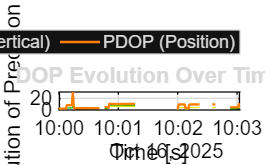

Unrecognized function or variable 'Pmd'.

function out = tdoaIntegrity5G(toa_s, gNBPos_ENU, x0_ENU, sigmaTOA_s, cfg)

%TDOAINTEGRITY5G WLS position and Gaussian HPL/VPL for 5G DL-TDOA.
%
% Inputs (all transmitters must be in the same order):
%   toa_s         [M x 1] measured TOA, in seconds, with known PRS
%                 transmission scheduling offsets already removed.
%   gNBPos_ENU     [M x 3] gNB positions, in metres (E,N,U).
%   x0_ENU        [1 x 3] initial user position, in metres (E,N,U).
%   sigmaTOA_s    scalar or [M x 1] individual TOA standard deviations [s].
%   cfg           optional struct:
%     dim           3 (default) or 2 (fixed height x0_ENU(3)).
%     pH            horizontal tail risk, default 5e-8.
%     pV            vertical two-sided tail risk, default 5e-8.
%     biasBound_s   [M x 1] bound on |uncorrected TOA bias| in seconds;
%                   default zeros (NO protection from unmodelled faults).
%     Ctoa_s2       [M x M] full covariance of TOA errors in s^2;
%                   default diag(sigmaTOA_s.^2). If supplied, overrides it.
%     maxIter       maximum Gauss-Newton iterations (default 40).
%     tol_m         convergence threshold in metres (default 1e-6).
%
% Outputs: out.valid, out.message, out.xhat_ENU, out.G, out.R_m2,
%          out.P_ENU_m2, out.HPL_m, out.VPL_m, out.HPL_random_m,
%          out.VPL_random_m, out.Hbias_m, out.Vbias_m, out.residual_m.
%
% CAUTION: PLs are local Gaussian-model bounds, not certified integrity.
% Non-Gaussian NLOS, unmodelled clock biases, incorrect covariance and
% convergence to a wrong position can invalidate the bounds.

if nargin < 5 || isempty(cfg), cfg = struct(); end
if ~isfield(cfg,'dim'),         cfg.dim = 3; end
if ~isfield(cfg,'pH'),          cfg.pH = 5e-8; end
if ~isfield(cfg,'pV'),          cfg.pV = 5e-8; end
if ~isfield(cfg,'maxIter'),     cfg.maxIter = 40; end
if ~isfield(cfg,'tol_m'),       cfg.tol_m = 1e-6; end

c = 299792458;
toa = toa_s(:);
bs  = double(gNBPos_ENU);
x   = double(x0_ENU(:)).';
M   = numel(toa);
d   = cfg.dim;

out = struct('valid',false,'message','', 'xhat_ENU',nan(1,3), ...
    'G',[],'R_m2',[],'P_ENU_m2',nan(3), ...
    'HPL_m',nan,'VPL_m',nan, ...
    'HPL_random_m',nan,'VPL_random_m',nan, ...
    'Hbias_m',nan,'Vbias_m',nan,'residual_m',[], ...
    'iterations',0);

if ~ismember(d,[2 3]) || size(bs,1) ~= M || size(bs,2) ~= 3 ...
        || numel(x) ~= 3 || M < d+1
    out.message = 'Invalid dimensions or insufficient gNBs.';
    return;
end
if any(~isfinite([toa; bs(:); x(:)]))
    out.message = 'Non-finite TOA, position or gNB coordinates.';
    return;
end
if ~(cfg.pH>0 && cfg.pH<1 && cfg.pV>0 && cfg.pV<1)
    out.message = 'Tail probabilities must lie strictly between 0 and 1.';
    return;
end

if isscalar(sigmaTOA_s)
    sigma = repmat(double(sigmaTOA_s),M,1);
else
    sigma = double(sigmaTOA_s(:));
end
if numel(sigma) ~= M || any(~isfinite(sigma)) || any(sigma <= 0)
    out.message = 'Invalid TOA standard deviations.';
    return;
end

if isfield(cfg,'biasBound_s')
    b = double(cfg.biasBound_s(:));
else
    b = zeros(M,1);
end
if numel(b)~=M || any(~isfinite(b)) || any(b<0)
    out.message = 'Invalid absolute TOA bias bounds.';
    return;
end

if isfield(cfg,'Ctoa_s2') && ~isempty(cfg.Ctoa_s2)
    Ctoa = double(cfg.Ctoa_s2);
else
    Ctoa = diag(sigma.^2);
end
if ~isequal(size(Ctoa),[M M]) || any(~isfinite(Ctoa(:)))
    out.message = 'Invalid TOA covariance matrix.';
    return;
end
Ctoa = 0.5*(Ctoa+Ctoa.');

% First gNB is the reference: delta_tau_i1 = toa_i - toa_1.
D = [-ones(M-1,1), eye(M-1)];
z = c * (D * toa);                    % TDOA observations [m]
R = (c^2) * (D * Ctoa * D.');       % correlated TDOA covariance [m^2]
[L, cholFlag] = chol(R,'lower');
if cholFlag ~= 0
    out.message = 'TDOA covariance is not positive definite.';
    return;
end

converged = false;
for iter = 1:cfg.maxIter
    [h,G3,geometryOK] = modelTDOA(x,bs);
    if ~geometryOK
        out.message = 'User position coincides with a gNB.';
        return;
    end
    G = G3(:,1:d);
    A = L\G;
    singularVals = svd(A);
    if numel(singularVals)<d || singularVals(end) <= 1e-10*singularVals(1)
        out.message = 'Unobservable / ill-conditioned gNB geometry.';
        return;
    end
    residual = z-h;
    delta = A \ (L\residual);       % WLS Gauss-Newton correction [m]
    if norm(delta)<cfg.tol_m
        converged = true;
        break;
    end

    % Backtracking: avoid accepting a step that increases WLS cost.
    cost0 = norm(L\residual)^2;
    step = 1;
    accepted = false;
    for j = 1:20
        candidate = x;
        candidate(1:d) = x(1:d) + step*delta.';
        [h2,~,ok] = modelTDOA(candidate,bs);
        if ok && norm(L\(z-h2))^2 < cost0
            x = candidate;
            accepted = true;
            break;
        end
        step = step/2;
    end
    if ~accepted
        out.message = 'Gauss-Newton line search failed.';
        return;
    end
    if norm(step*delta) < cfg.tol_m
        converged = true;
        break;
    end
end
if ~converged
    out.message = 'WLS estimator did not converge.';
    return;
end

[h,G3,geometryOK] = modelTDOA(x,bs);
if ~geometryOK
    out.message = 'Invalid final geometry.';
    return;
end
G = G3(:,1:d);
A = L\G;
[Q,U] = qr(A,0);
singularVals = svd(A);
if singularVals(end) <= 1e-10*singularVals(1)
    out.message = 'Unobservable final geometry.';
    return;
end

% P = inv(G' * inv(R) * G), computed via a stable QR factorization.
Uinv = U\eye(d);
P = Uinv*Uinv.';

% K maps TDOA range errors [m] to estimated position errors [m].
K = U\(Q.'/L);
% A bounded TOA bias affects all TDOAs through D (not independent).
Ktoa = c*K*D;                       % position error [m] per TOA bias [s]

hBias = sum(vecnorm(Ktoa(1:2,:).*b.',2,1));
Cen = P(1:2,1:2);
maxEigenvalue = max(eig(0.5*(Cen+Cen.')));
hRandom = sqrt(-2*log(cfg.pH)) * sqrt(max(0,maxEigenvalue));

P3 = nan(3);
P3(1:d,1:d) = P;
if d==3
    vBias = sum(abs(Ktoa(3,:)).*b.');
    vRandom = sqrt(2)*erfcinv(cfg.pV)*sqrt(max(0,P(3,3)));
    vpl = vRandom + vBias;
else
    vBias = nan;
    vRandom = nan;
    vpl = nan;                      % Height is fixed, not estimated.
end

out.valid = true;
out.message = 'OK (conditional Gaussian PL, not fault-certified).';
out.xhat_ENU = x;
out.G = G;
out.R_m2 = R;
out.P_ENU_m2 = P3;
out.HPL_random_m = hRandom;
out.VPL_random_m = vRandom;
out.Hbias_m = hBias;
out.Vbias_m = vBias;
out.HPL_m = hRandom+hBias;
out.VPL_m = vpl;
out.residual_m = z-h;
out.iterations = iter;
end

function [h,G3,ok] = modelTDOA(x,bs)
% h_i = norm(x-s_i) - norm(x-s_1) [m].
    differences = x-bs;
    ranges = sqrt(sum(differences.^2,2));
    ok = all(ranges > 1e-6);
    if ~ok
        h = []; G3 = [];
        return;
    end
    directions = differences./ranges;
    h = ranges(2:end) - ranges(1);
    G3 = directions(2:end,:) - directions(1,:);
end
